# MUSIC

Se implementó el algoritmo MUSIC para detectar la dirección de fuentes de audio. En las pruebas que se muestran aquí se tienen 2 fuentes sonando al mismo tiempo, que fueron grabadas por 3 microfonos distintos. 

Los microfonos, estaban en un arreglo triangular, donde cada lado del triangulo media 18cm.

Las fuentes se ubicaban a -30 grados y 90 grados de la normal a la linea que unia los primeros dos microfonos, estos ángulos son las direcciones de arribo a investigar.


%Abrimos las señales
[signal1, Fs] = audioread("wav_mic1_2_fuentes.wav");
[signal2, Fs] = audioread("wav_mic2_2_fuentes.wav");
[signal3, Fs] = audioread("wav_mic3_2_fuentes.wav");
tArray = (0:length(signal1)-1)*(1/Fs);
fftCalculator = FFTCalculator()

fftCalculator =   FFTCalculator with no properties.


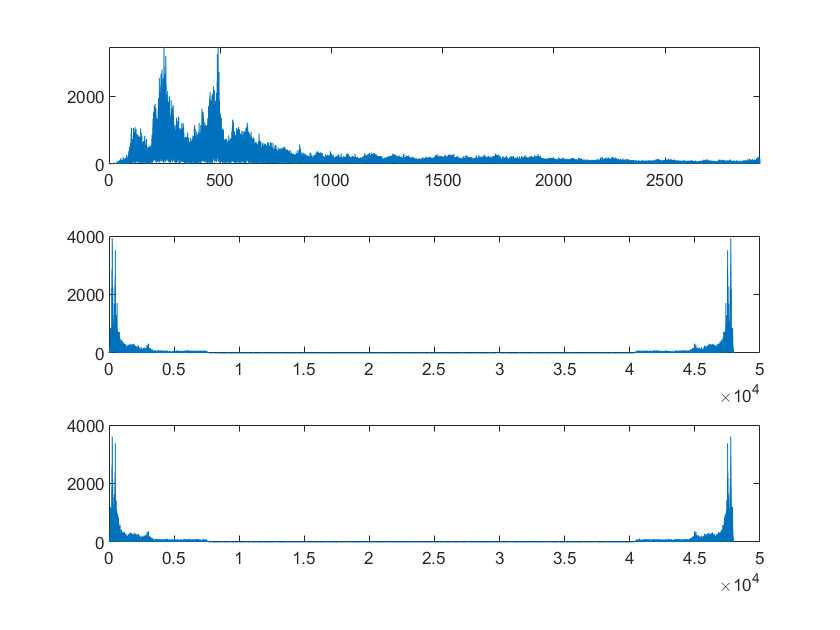

%Obtenemos el espectro de las señales
[freqs, spectrum1] = fftCalculator.getFFT(signal1, tArray);
[freqs, spectrum2] = fftCalculator.getFFT(signal2, tArray);
[freqs, spectrum3] = fftCalculator.getFFT(signal3, tArray);


figure()
subplot(3,1,1)
plot(freqs, abs(spectrum1))
subplot(3,1,2)
plot(freqs, abs(spectrum2))
subplot(3,1,3)
plot(freqs, abs(spectrum3))

Basado en el espectro convendría hacer una busqueda en un rango de 200 a 600


signals = [spectrum1, spectrum2, spectrum3];
distanceBetweenMics = 0.18;
nSources = 2;
phases = [0,0,60];
%Frecuencias y direcciones que vamos a buscar 
minFreq = 600;
maxFreq = 650;
minAngle = -180;
maxAngle = 180;

%Creamos el detector MUSIC
musicDetector = MUSICDetector(nSources, signals, tArray, distanceBetweenMics, phases);

%Primero obtendremos el espectro para inspeccionar que realmente haya picos
%en las direcciones de las fuentes
[angles, freqs, timeDelays, musicSpectrum] = musicDetector.getMusicSpectrum(minFreq, maxFreq, minAngle, maxAngle);

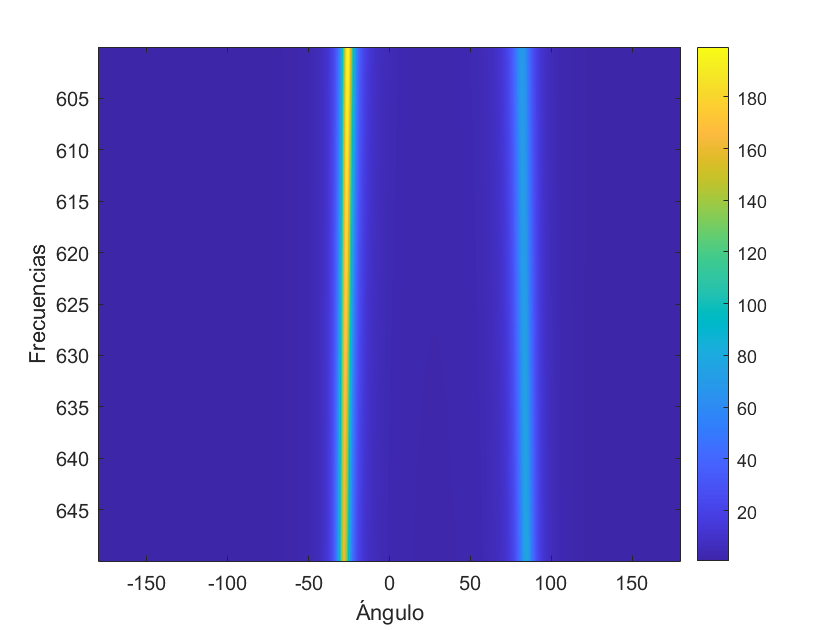

figure()
imagesc(angles, freqs, musicSpectrum)
xlabel("Ángulo")
ylabel("Frecuencias")
colorbar;

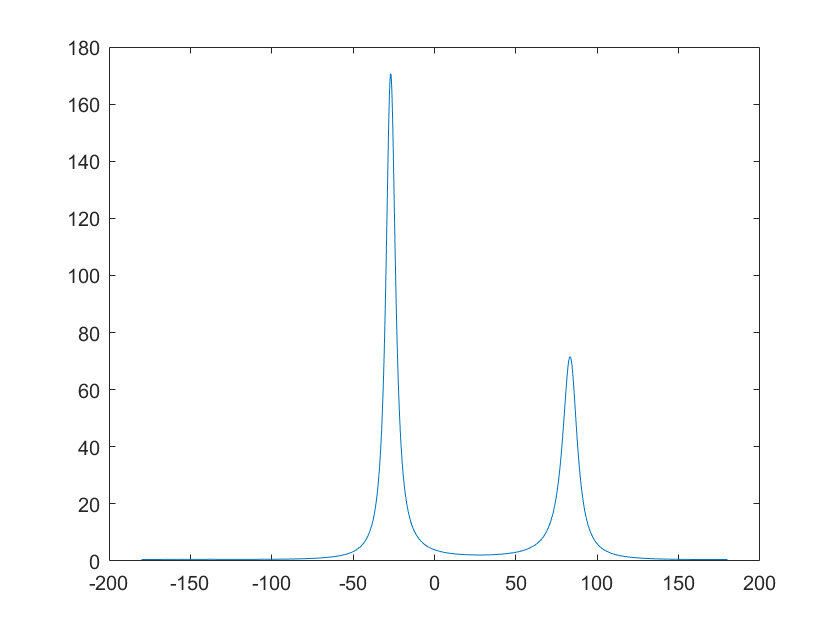

plot(angles, mean(musicSpectrum, 1))

Las fuentes reales se encontraban a -30 y 90 grados, lo cual coincide aproximadamente con el resultado obtenido.

[dirs, delays] = musicDetector.getSourcesDirections(minFreq, maxFreq, minAngle, maxAngle);
for i = 1:length(dirs)
    disp("Dirección de fuente "+string(i)+" "+dirs(i))
end

Dirección de fuente 1 -26.5633
Dirección de fuente 2 83.6518
